# Q2(a)

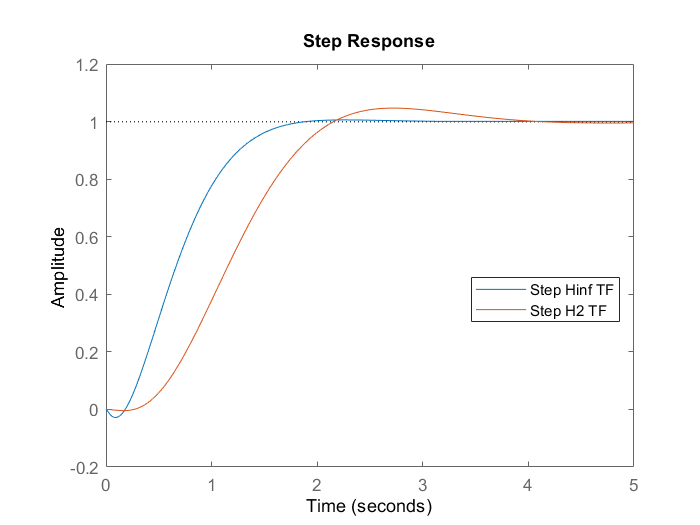

s = tf('s');
G1 = (s-10)/((s+1)*(s+10));
Wp = 1/(s+0.001);
Wu = (s+2)/(s+10);
P1 = [Wp -Wp*G1;
     0   Wu;
     1   -G1];
[K2,CL2,GAM2] = h2syn(P1,1,1);
[Kinf,CLinf,GAMinf] = hinfsyn(P1,1,1);

Tinf = feedback(G1*Kinf,1);
T2 = feedback(G1*K2,1);
step(Tinf,T2)
legend('Step Hinf TF','Step H2 TF','Location','best')

# Q2(b)

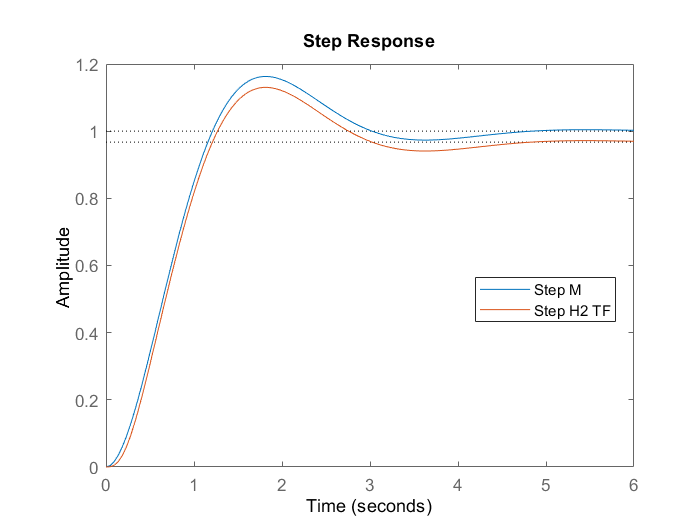

M = 4/(s^2+2*s+4);
G2 = 10*(s+2)/(s+1)^3;
W = 0.1*(s+1)/(s+10);
P2 = [0 W;
      M -G2;
      1 -G2];

[K2,CL2,GAM2] = h2syn(P2,1,1);

T2 = feedback(G2*K2,1);
step(M,T2)
legend('Step M','Step H2 TF','Location','best')